addpath('Data', 'lib', 'lib/utils')
load('Trainset.mat')
load('Finaltest.mat')

seed = 123;

# NM836 Coursework 2 - Results

## Dataset of $d=36$ features and $n$ samples:

## 
$$\mathcal{D}=\left\{\mathbf{x}_p : p\in[1, d]\subset\mathbb{N}^d \right\}\in\mathbb{R}^{n\times d}$$


The dataset labels are the set of time-series samples of the 'Main Engine Consumed Fuel':

#### $\mathbf{X}=\mathcal{D}\setminus\{\mathbf{x}_{35}\}\in\mathbb{R}^{n\times (d-1)}$ - Input Features

#### $\mathbf{y}=\mathbf{x}_{35}\in\mathbb{R}^n$ - Labels

d = 36;
n = size(Trainset, 1);

X = Trainset(:, setdiff(1:end, 35));
y = Trainset(:, 35);

## Network Architecture

ANN with: 

$s_1 =d-1=35$ in the input layer (non including bias),

$s_2 \in \left\lbrace 20,40,70,80,100\right\rbrace$neurons in the hidden layer (explored as hyperparameter, not including bias),

$s_3 =1$ output neuron.

s1 = size(X, 2);
s2 = 100;
s3 = size(y, 2);

layers = [s1, s2, s3];

Weights initialisation:

rng(seed)
[W, w_vec] = weights_init(layers);

## Scaling Data in the interval $\left(0,1\right)$

[X,X_centerValue,X_scaleValue] = normalize(X,"range");
[y,y_centerValue,y_scaleValue] = normalize(y,"range");

act_fun = "sigmoid";
hypothesis = @(X, W) predict(X, W, act_fun)*y_scaleValue + y_centerValue;
lambda_range = logspace(-4, 2, 10);
lambda = 2e-3;

## Optimiser

cost_func = @(w) nnCostFunction(w, s1, s2, s3, X, y, lambda, act_fun);
tic
options.MaxIter = 100;
[w_vec_opt, cost_opt_his, i] = fmincg(cost_func,w_vec, options);
cost_opt = cost_opt_his(end);
fprintf("Time Elapsed: %2.3f s", toc)

Time Elapsed: 34.343 s

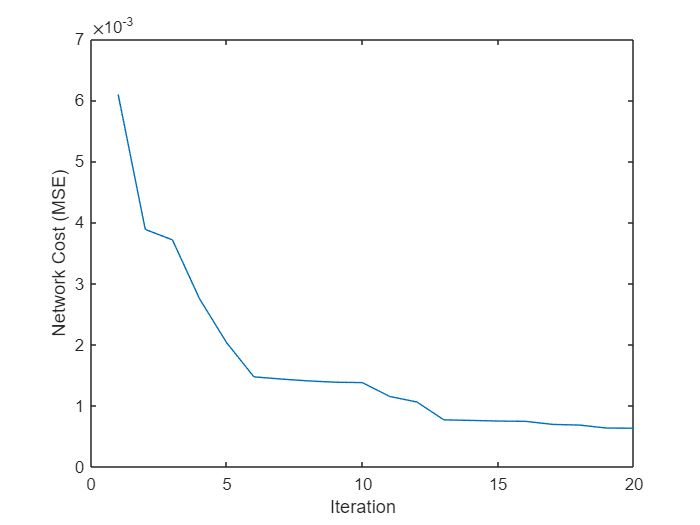

figure(1);
plot(1:i, cost_opt_his);
xlabel('Iteration');
ylabel('Network Cost (MSE)');

W_opt = reshape_weights_vector(w_vec_opt, s1, s2, s3);
y_hat = hypothesis(X, W_opt);